# Getting Started with the Trade-Off Diagram Toolbox for PID Control Design

## 1. Introduction

This Live Script introduces the **Trade-Off Diagram Toolbox for PID Control Design**, a MATLAB toolbox that supports the design of PID controllers using trade-off diagrams as proposed by Garpinger et al. [1].

Traditional tuning methods (e.g., Ziegler-Nichols) often fail to address these trade-offs systematically. The Garpinger method, based on visual trade-off diagrams, provides a structured way to select controller gains that balance performance and robustness. 

This toolbox provides three core functions:

- `calculateTradeoff`: Computes trade-off curves for a given process model.

- `calculateCascadedTradeoff`: Extends the analysis to cascaded control structures.

- `plotTradeoff`: Visualizes trade-off diagrams and highlights optimal controller settings.

In addition to the functions, the toolbox includes:

- A Live Script explaining the **theoretical background** of [trade-off diagrams](matlab:open('..\Examples\BackgroundTradeoff.m')) and [design criteria](matlab:open('..\Examples\BackgroundDesignCriteria.m')).

- A field study demonstrating the [**application of the method**](matlab:open('..\Examples\FieldstudyTradeoff.m')) to a DC motor, including real-world data, controller design, and experimental validation.

The field study [2] shows how trade-off diagrams can be used to tune both inner and outer loops of a cascaded control system, combining feedback and feedforward control for precise trajectory tracking.

The toolbox is compatible with MATLAB R2025a and later, and is distributed as an open-source project via GitHub.

This Getting Started Guide will walk you through:

- Installation

- Basic usage of the functions

- Interpretation of trade-off plots

- Application to real-world motor control

## **2. Installation**

The **Trade-Off Diagram Toolbox for PID Control Design** is compatible with Matlab 2025a or later and provided via

*Option 1:*

a) From Matlab $->$ Apps $->$ Get More Apps $->$ Search for "Trade-Off Diagram Toolbox for PID Control Design" $->$ Add $->$ Add to Matlab

This will download the toolbox to your local installation and set the Matlab path appropriately.

*Option 2:*

a) From Matlab $->$ Apps $->$ Get More Apps $->$ Search for "Trade-Off Diagram Toolbox for PID Control Design" $->$ Add $->$ Download Only

b) extract the contents of the downloaded zip-archive to a local folder

c) Either open the Matlab-project file "TradeoffToolbox.prj" or set the Matlab Path to include

   - JRC-ISIA-matlab-addon-pid-garpingers-tradeoff-diagrams-VERSION

   - JRC-ISIA-matlab-addon-pid-garpingers-tradeoff-diagrams-VERSION/Toolbox

   - JRC-ISIA-matlab-addon-pid-garpingers-tradeoff-diagrams-VERSION/Toolbox/Helpers

   - JRC-ISIA-matlab-addon-pid-garpingers-tradeoff-diagrams-VERSION/Toolbox/doc

   - JRC-ISIA-matlab-addon-pid-garpingers-tradeoff-diagrams-VERSION/Toolbox/Examples

   - JRC-ISIA-matlab-addon-pid-garpingers-tradeoff-diagrams-VERSION/Toolbox/Data

*Option 3:*

a) go to https://www.mathworks.com/matlabcentral/fileexchange/ $->$ search for "Trade-Off Diagram Toolbox for PID Control Design" and download the provided zip-archive

b)+c): see Option 2

### Included Functions

After installation, the following functions will be available:

- `calculateTradeoff` – Computes trade-off diagram criteria for a given plant.

- `calculateCascadedTradeoff` – Performs trade-off analysis for cascaded control structures.

- `plotTradeoff` – Visualizes trade-off diagrams and highlights optimal controller settings.

### Included Live Scripts

The toolbox also includes two MATLAB Live Scripts:

- [`BackgroundTradeoff.m`](matlab:open('..\Examples\BackgroundTradeoff.m')) – Explains the theoretical background of trade-off diagrams.

- [`BackgroundDesignCriteria.m`](matlab:open('..\Examples\BackgroundDesignCriteria.m')) – Explains the theoretical background of the design criteria for trade-off diagrams.

- [`FieldstudyTradeoff.m`](matlab:open('..\Examples\FieldstudyTradeoff.m')) – Demonstrates a complete PID tuning workflow using real-world data and validation on a DC motor.

## 3. Toolbox Contents

The **Trade-Off Diagram Toolbox for PID Control Design** provides three core MATLAB functions and two Live Scripts that support the design and analysis of PID controllers using trade-off diagrams. These diagrams help visualize the balance between control performance and robustness, enabling systematic controller tuning. 

### Core Functions

**1.** `calculateTradeoff`

This function computes the design criteria required to generate Garpinger-style trade-off diagrams for PID controllers. It analyzes whether the plant is proportional or integral, with or without time delay, and calculates matrices for:

- Stability

- Robustness (maximum sensitivity)

- Performance (integral of absolute error, IAE) for disturbance rejection and setpoint tracking

The function interpolates over controller gains (the gains that are considered are depending on the plant type) and supports adjustable resolution via name-value pairs.

**2.** `calculateCascadedTradeoff`

This function extends the trade-off analysis to cascaded control loops. It calculates the effective plant model based on the inner loop plant and controller, and the outer loop plant. Depending on whether the resulting system is proportional or integral, it interpolates over the relevant controller gains. The output includes matrices for stability, robustness, and performance, similar to the single-loop version.

**3.** `plotTradeoff`

This function visualizes the trade-off between robustness and performance using contour plots. It generates two figures:

- One for **disturbance rejection**

- One for **setpoint tracking**

The plots show regions of stability, robustness contours ($M_{\mathrm{st}}$), and performance contours (IAE). The function also supports advanced options such as:

- External figure windows

- Matrix upsampling

- Pareto front smoothing using various methods (e.g., Gaussian, LOWESS, Savitzky-Golay)

These visualizations help identify optimal PID controller settings based on design priorities.

[`BackgroundTradeoff.m`](matlab:open('..\Examples\BackgroundTradeoff.m'))

Explains the theoretical foundation of trade-off diagrams, including the performance and robustness criteria used (IAE, IE, $M_{\mathrm{st}}$). 

[`FieldstudyTradeoff.m`](matlab:open('..\Examples\FieldstudyTradeoff.m'))

Demonstrates a complete PID tuning workflow using real-world data from a DC motor. It includes system identification, controller design using trade-off plots, and experimental validation. The script also covers cascaded control.

## 4. Quick Start Example

This section provides minimal working examples to help you get started quickly with the Trade-Off Diagram Toolbox for PID Control Design. The examples demonstrate how to compute and visualize trade-off diagrams for both standard and cascaded PID control loops.

### Example 1: Standard PID Control Loop

To generate a trade-off diagram for a single-loop PID controller, define a plant model and call the `calculateTradeoff` and `plotTradeoff` functions:

ex1.plant = tf(1, [1 2 1], 'IoDelay', 0.5);  % User-defined plant model
ex1.dataComplete = calculateTradeoff(ex1.plant, 5, 2.5, 0, 'ResolutionSpec', 'low');
plotTradeoff(ex1.dataComplete);

This example computes the full trade-off diagram with low resolution for quick visualization. You can refine the analysis by focusing on a smaller region with higher resolution:

ex1.dataRelevant = calculateTradeoff(ex1.plant, 1.5, 0.6, 0, 'ResolutionSpec', 'low');
plotTradeoff(ex1.dataRelevant);

This allows you to zoom in on the most relevant controller gain combinations and obtain more detailed trade-off plots.

### Example 2: Cascaded PID Control Loop

For cascaded control systems, such as those used in motor position control, use the `calculateCascadedTradeoff` function. Define the inner and outer loop models and the inner loop controller:

ex2.Pi = tf(1, [1 2 1], 'IoDelay', 0.5);  % Inner loop plant
s = tf("s");
ex2.Ci = 0.8 + 0.5/s;                    % Inner loop controller
ex2.Po = 1/s;                            % Outer loop plant
ex2.data = calculateCascadedTradeoff(ex2.Pi, ex2.Po, ex2.Ci, 1.2, 0, 2);
plotTradeoff(ex2.data);

This example computes the trade-off diagram for the outer loop controller, taking into account the dynamics of the inner loop. The resulting plots help identify optimal PID gains for the outer loop while considering the closed-loop behavior of the entire cascaded system.

These examples provide a starting point for exploring the toolbox. For more advanced usage, including experimental validation, refer to the included Live Script: 

open('FieldstudyTradeoff.m')

## 5. Interpreting the Trade-Off Plots

The trade-off plots generated by the toolbox visualize the relationship between **control performance and robustness** for a range of PID controller gains. These plots are based on the methodology proposed by Garpinger et al. and help identify optimal controller settings for specific design goals.

### Key Metrics

**Performance** is evaluated using:

- **IE (Integral Error)**: Measures the total control error over time.

- **IAE (Integral of Absolute Error)**: Emphasizes persistent deviations and is more sensitive to overshoot and long settling times.

**Robustness** is assessed using:

- **Maximum Sensitivity (**$M_{\mathrm{st}}$**)**: Indicates how sensitive the system is to disturbances and model uncertainties. Lower values imply higher robustness.

**Plot Features**

- **Blue contour lines** represent constant IAE-values (**performance**).

- **Red contour lines** represent constant $M_{\mathrm{st}}$-values (**robustness**).

- **Grey regions** indicate **unstable** controller configurations.

- **Green line (Pareto front)** shows the optimal balance between performance and robustness for **disturbance rejection**.

- **Magenta line** (**Pareto front**) shows the optimal balance for **setpoint tracking**.

Each point in the plot corresponds to a specific combination of PID gains. Moving:

- **Left of the Pareto** front increases overshoot (IAE > IE).

- **Right of the Pareto** front reduces robustness (Mst increases).

- **Along the Pareto fronts** allows selection of gains that best match application-specific priorities.

### Practical Use

By analyzing these plots, you can:

- Select PID gains that minimize error without compromising stability.

- Compare trade-offs between fast response and robustness.

- Tune controllers for either disturbance rejection or setpoint tracking, depending on your system’s needs.

This visual approach provides a systematic and intuitive method for PID tuning, especially in applications where performance and robustness must be carefully balanced.

For more advanced background refer to the included Live Script: 

open('BackgroundTradeoff.m')

## 6. Detailed Workflow

This section outlines how to use the toolbox functions in a structured way to design PID controllers using trade-off diagrams. It covers both single-loop and cascaded control systems.

### Step 1: Define the Plant Model

Start by specifying the transfer function of your system. For example:

dw.plant = tf(1, [1 2 1], 'IoDelay', 0.5);

This defines a second-order system with a time delay.

### Step 2: Compute Trade-Off Data

Use the `calculateTradeoff` function to compute the design criteria for a range of PID gains. The resolution can be selected using the ‘ResolutionSpec’ parameter, which determines the resolution via the controller gains on the x and y axes. 

dw.kp = 2;  
dw.ki = 1;  
dw.kd = 0.1; 
dw.resolutionSpec = "medium"; 
dw.data = calculateTradeoff(dw.plant, dw.kp, dw.ki, dw.kd, 'ResolutionSpec', dw.resolutionSpec);

- `kp`, `ki`, and `kd` define the maximum controller gains to be considered.

- `'ResolutionSpec'` controls the resolution of the output matrices. Higher resolution requires more computing time, but resolves the individual lines more accurately when drawing. 'ResolutionSpec' can be either a numeric vector [`nY nX`] specifying the number of points in Y abd X-direction, or a string: '`low`', '`medium`', '`high`'.

The function automatically detects whether the plant is proportional or integral and interpolates over the appropriate gain parameters. In this example, the plant is proportional, which is why $k_\mathrm{i}$ is interpolated via $k_\mathrm{p}$ and $k_\mathrm{d}$ is kept constant at the specified value.

### Step 3: Visualize the Trade-Off Diagram

Use the `plotTradeoff` function to generate contour plots:

dw.numberOfPerformanceLines = 4;
dw.robustnessLevels = str2num("[1.1, 1.2, 1.4, 1.6, 2.0, 2.5]");
dw.upsampleScale = "low";
dw.externalFigureWindow = false;
dw.smoothParetoFront.method = "movmean";
dw.smoothParetoFront.window = 7;
[dw.figDistRej, dw.figDistRej] = plotTradeoff(dw.data, ...
    "NumberOfPerformanceLines", dw.numberOfPerformanceLines, ...
    "RobustnessLevels", dw.robustnessLevels, ...
    "UpsampleScale", dw.upsampleScale, ...
    "ExternalFigureWindow", dw.externalFigureWindow, ...
    "SmoothParetoFrontMethod", dw.smoothParetoFront.method, ...
    "SmoothParetoFrontWindow", dw.smoothParetoFront.window);

This produces two plots:

- One for **disturbance rejection**

- One for **setpoint tracking**

You can customize the visualization using optional parameters such as:

- `'RobustnessLevels'` – specify contour levels for maximum sensitivity as vector. Values exceeding the maximum of the pareto fronts will be ignored, as this leads to overshoot and a longer settling time of the closed loop. The lines are labeld with the $M_{\mathrm{st}}$ value.

- `'NumberOfPerformanceLines'` – set the number of IAE contours as scalar. The lines are displayed evenly distributed along the y-axis up to the maximum of the Pareto front and labeled with the IAE value.

- `'SmoothPareto'` – apply smoothing to the Pareto front. Since only discrete values are calculated and these are subject to numerical inaccuracies, filtering is necessary. The Matlab function `smoothdata` is used for this purpose and the parameters are passed through. In addition, ‘off’ can be selected if the Pareto fronts are not to be filtered and ‘auto’ if the automatic filtering of the method is to be applied.

- `'ExternalFigureWindow'` – display plots in separate windows, if desired. Use a boolean value (`true`, `false`) for this parameter.

### Cascaded Control Workflow

The following structure is used for cascaded control loops, whereby the disturbance affects the input of the inner loop.

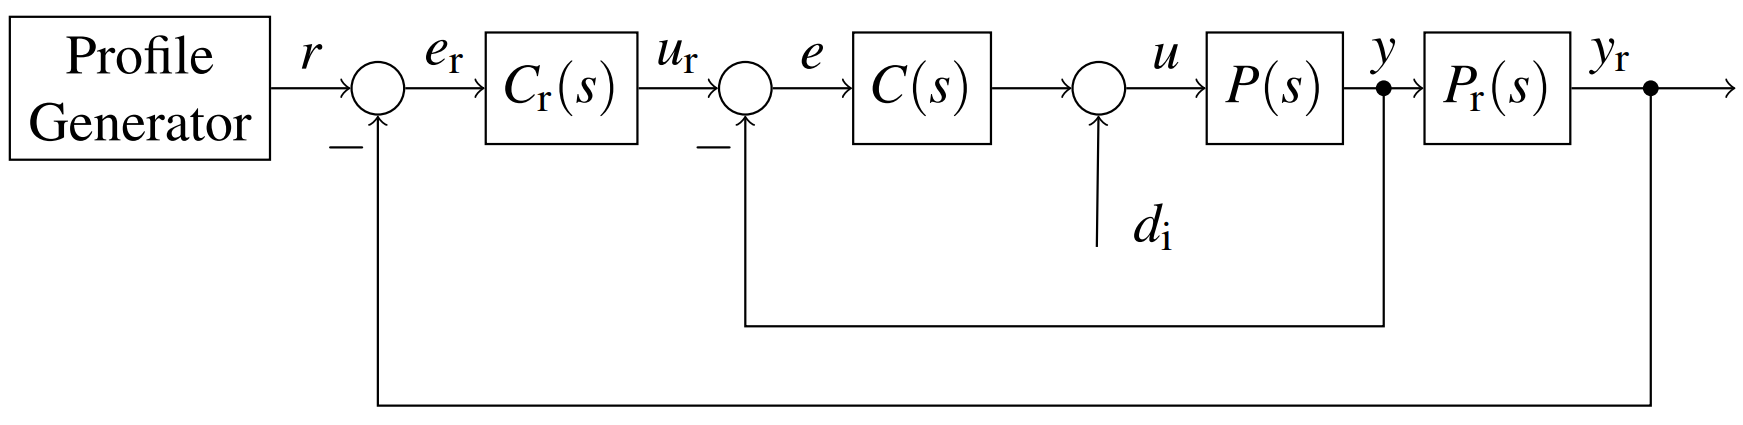

For cascaded systems, follow these steps:

1. Define the inner loop plant and controller:

ccw.Pi = tf(1, [1 2 1], 'IoDelay', 0.5);
s = tf("s");
ccw.Ci = 0.8 + 0.5/s;

2. Define the outer loop plant:

ccw.Po = 1/s;

3. Compute trade-off data for the outer loop controller:

ccw.kp = 0.8;  % Define maximum proportional gain
ccw.ki = 0;  % Define maximum integral gain
ccw.kd = 1.5;      % Define maximum derivative gain
ccw.resolutionSpec = "medium"; % Resolution of the design criteria matrices 
ccw.data = calculateCascadedTradeoff(ccw.Pi, ccw.Po, ccw.Ci, ccw.kp, ccw.ki, ccw.kd);

4. Visualize the trade-off plots:

ccw.numberOfPerformanceLines = 4;
ccw.robustnessLevels = str2num("[1.1, 1.2, 1.4, 1.6, 2.0, 2.5]");
ccw.upsampleScale = "low";
ccw.externalFigureWindow = false;
ccw.smoothParetoFront.method = "movmean";
ccw.smoothParetoFront.window = 7;
[ccw.figDistRej, ccw.figDistRej] = plotTradeoff(ccw.data, ...
    "NumberOfPerformanceLines", ccw.numberOfPerformanceLines, ...
    "RobustnessLevels", ccw.robustnessLevels, ...
    "UpsampleScale", ccw.upsampleScale, ...
    "ExternalFigureWindow", ccw.externalFigureWindow, ...
    "SmoothParetoFrontMethod", ccw.smoothParetoFront.method, ...
    "SmoothParetoFrontWindow", ccw.smoothParetoFront.window);

This workflow allows you to design the outer loop controller while accounting for the closed-loop behavior of the inner loop.

## Conclusion

The Trade-Off Diagram Toolbox for PID Control Design provides a structured, visual approach to PID controller tuning. By combining performance and robustness criteria into trade-off plots, the toolbox enables users to make informed design decisions based on application-specific requirements.

Whether you're working with standard feedback loops or cascaded control systems, the toolbox helps you:

- Visualize the impact of controller gains on system behavior

- Identify optimal tuning points using Pareto front analysis

- Balance fast response with robustness against disturbances and uncertainties

- Apply the methodology to real-world systems, as demonstrated in the included field study

With its open-source availability and integration into MATLAB, the toolbox is designed to be both accessible and extensible. It supports academic research, industrial applications, and educational use.

For further exploration, refer to the included Live Scripts, consult the referenced literature, and consider contributing to the project via GitHub.

## References

[1] Garpinger, O., Hägglund, T., & Åström, K. J. (2014). Performance and robustness trade-offs in PID control. Journal of Process Control, 24(4), 568–577. [https://doi.org/10.1016/j.jprocont.2014.02.020](https://doi.org/10.1016/j.jprocont.2014.02.020) 

[2] Hoher, S. & Rehrl, J. (2025). Analysis and tuning of PID controller gains for DC servo drives using Garpinger’s trade-off plots. *ARW Proceedings* 25(1), 19-24. [https://doi.org/10.34749/3061-0710.2025.3](https://doi.org/10.34749/3061-0710.2025.3)

## Support and Feedback

If you encounter issues while using the Trade-Off Diagram Toolbox for PID Control Design, or if you have suggestions for improvements, there are several ways to get support and contribute to the project.

### Reporting Issues

If you discover a bug, unexpected behavior, or incorrect results, please report it via the GitHub issue tracker, include a short description, the MATLAB version you are using, and a minimal example if possible.

### Feature Requests

If you have ideas for new features—such as additional visualization options, support for other controller types, or integration with Simulink—feel free to open a feature request on GitHub.

### Contributing

The toolbox is open-source. Contributions are welcome in the form of:

- Code improvements

- Documentation enhancements

- New examples or case studies

### Contact

For academic or collaboration inquiries, you may contact the authors directly:

- Simon Hoher, simon.hoher@fh-salzburg.ac.at, Salzburg University of Applied Sciences, JR Center for Intelligent and Secure Industrial Automation, Puch/Salzburg, Austria.

- Jakob Rehrl, jakob.rehrl@fh-salzburg.ac.at, Salzburg University of Applied Sciences, JR Center for Intelligent and Secure Industrial Automation, Puch/Salzburg, Austria.